# Room Impulse Response Simulation with the Image-Source Method and HRTF Interpolation with Head Tracking

This project aims to estimate the impulse response (RIR) of a box-shaped room using the image-source method and obtain the binaural reproduction of a sound source in the room. Custom-made hardware built with an Arduino board and an inertial measurement unit (IMU) is utilized to track head orientation and control the direction of arrival of a sound source by applying head-related transfer functions (HRTF).

The project also offers an option for simulating head movement without using external hardware for head tracking.

#### Required Hardware

- Arduino Uno

- Invensense MPU-9250 (gyroscope, accelerometer, & magnetometer)

Or set isUseArduino to false. A simulation of head movements will be performed instead.

#### Hardware Connection

Connect the Invensense MPU-9250 to the Arduino Uno board as shown in the figure below (skip if not using Arduino).

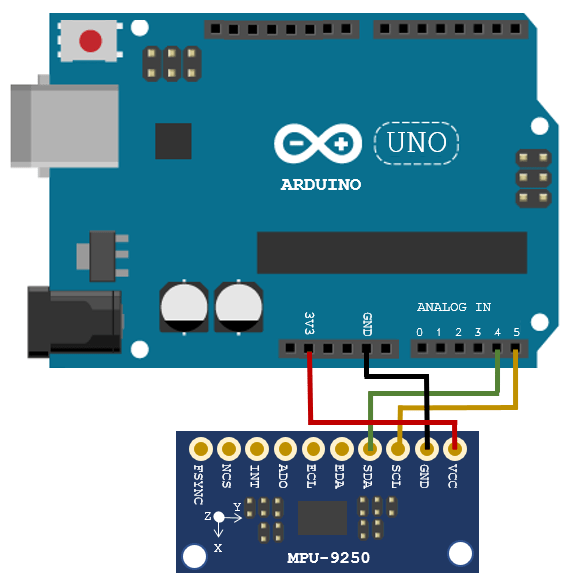

#### Required Add-Ons

- MATLAB Support Package for Arduino Hardware (skip if not using Arduino)

- Sensor Fusion and Tracking Toolbox (skip if not using arduino)

- Audio Toolbox

- Navigation Toolbox

## Locate audio file.

audio_file = '.\audio\vocal_new_emotions.wav';

## Define Parameters (skip if reading data from saved file)

Define sampling frequency for audio. Note: reduce sampling frequency if modeling a reverberant room to avoid IMU overrun and audio underrun.

fs = 12000;

Define the room dimensions, in meters (width, length and height). Note: reduce the size if modeling a reverberant room to avoid IMU overrun and audio underrun.

room_dimensions = [5, 5, 3];

Define the receiver's coordinates in the room, in meters (x, y, z).

receiver_coords = [3, 3, 1];

Define the sound source's coordinates in the room, in meters (x, y, z).

source_coords = [2, 3, 1];

Define the walls' materials. Choose from 'wood', 'concrete',  'glass', 'plaster', 'fiberglass', 'ice'. Note: reverberant materials may result in IMU overruns and audio underruns.

material_floor = 'glass';
material_front = 'glass';
material_left = 'glass';
material_back = 'glass';
material_right = 'glass';
material_ceil = 'glass';

Locate HRTF dataset file (.mat). HRTF datasets from the AIR databases can be found in ".\ARIHRTFDatasets\", for example, "[.\ARIHRTFDatasets\NH2\hrtf_M_hrtf 256.mat](matlab:open('./ARIHRTFDatasets\NH2\hrtf_M_hrtf 256.mat'))".

HRTF_dataset_file = 'ReferenceHRTF.mat';

## Read Data From Saved File

Choose whether to read data from file.

isLoadFile = false;

Choose which file to be opened.

saved_data_file = '.\data\h_2023-05-10-19-38-14.txt';

Read data from the file. Save data in DataManager. See [DataManager.m](matlab:open('./DataManager.m')) for documentation.

myDataManager = DataManager();
if isLoadFile
    myDataManager.readFromFile(saved_data_file);
    myDataManager.show();
    room_dimensions = myDataManager.room_dimensions;
    receiver_coords = myDataManager.receiver_coords;
    source_coords = myDataManager.source_coords;
    material_floor = myDataManager.wall_materials{1}{1};
    material_front = myDataManager.wall_materials{1}{2};
    material_left = myDataManager.wall_materials{1}{3};
    material_back = myDataManager.wall_materials{1}{4};
    material_right = myDataManager.wall_materials{1}{5};
    material_ceil = myDataManager.wall_materials{1}{6};
    wall_materials = myDataManager.wall_materials;
    fs = myDataManager.fs;
    HRTF_dataset_file = myDataManager.HRTF_dataset_file;
    h_table = myDataManager.h_table;
    h = h_table{:, :};
else
    myDataManager.room_dimensions = room_dimensions;
    myDataManager.receiver_coords = receiver_coords;
    myDataManager.source_coords = source_coords;
    myDataManager.wall_materials = {material_floor, material_front, material_left, material_back, material_right, material_ceil};
    myDataManager.fs = fs;
    myDataManager.HRTF_dataset_file = HRTF_dataset_file;
end

## Plot Room

Plot the room space along with the receiver (red circle) and transmitter (blue x). See [plotRoom.m](matlab:open('./plotRoom.m')) for implementation.

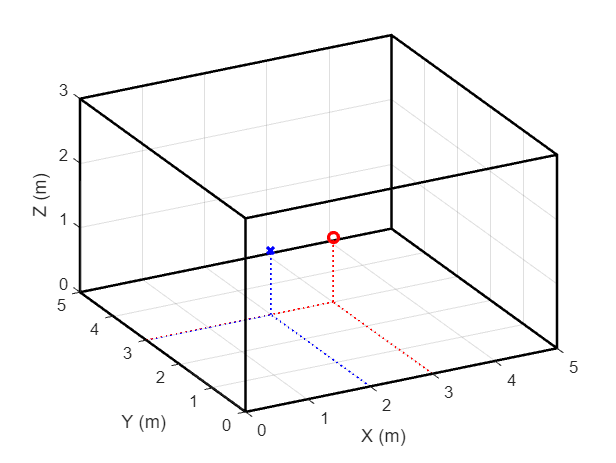

fig = figure;
plotRoom(room_dimensions,receiver_coords,source_coords,fig);

## Hardware Configuration

Choose whether to connect an Arduino board.

isUseArduino = false;

Create an arduino object. Check bus port if not 'COM7'. Include the I2C library.

if isUseArduino
    port = 'COM7';
    arduino = arduino(port, 'Uno', 'Libraries', 'I2C');
end

Create the Invensense MPU-9250 sensor object. Set sampler rate for the IMU.

if isUseArduino
    imu_fs = 100;
    imu = mpu9250(arduino,'SampleRate',imu_fs);
end

Accelerometer-Gyroscope Fusion. GyroscopeNoise and AccelerometerNoise is determined from datasheet.

if isUseArduino
    GyroscopeNoiseMPU9250 = 3.0462e-06; % GyroscopeNoise (variance) in units of rad/s
    AccelerometerNoiseMPU9250 = 0.0061; % AccelerometerNoise (variance) in units of m/s^2
    FUSE = imufilter('SampleRate',imu.SampleRate, 'GyroscopeNoise',GyroscopeNoiseMPU9250,'AccelerometerNoise', AccelerometerNoiseMPU9250);
end

## The Image-Source Method Explained

Note: this section briefly explains the image-source method. See [HelperImageSource.m](matlab:open('./HelperImageSource.m')) for full implementation.

Image-source is a geometric simulation method that models specular sound reflection paths between the source and receiver. It assumes that sound travels in straight lines (rays) which undergo perfect reflections when they encounter an obstacle (in our case, one of the four walls, the floor, or the ceiling of the room).

When a sound ray hits a wall, it spawns a mirrored "image" source. The image source is the symmetrical reflection of the original source with respect to the encountered boundary. Higher-order reflections (rays that reach the receiver after bouncing off multiple obstacles) are modeled by repeating the mirroring process with respect to each encountered obstacle. 

As an example, consider the ray that bounces off two walls and the floor before arriving at the receiver. Define the coordinates of the equivalent image for this ray.

imageSource = [-source_coords(1) -source_coords(2) -source_coords(3)];

The ray is modeled by the straight line connecting the image to the receiver. The length of this straight line is equal to the traveled distance from the original source to the receiver along the reflected ray.

Visualize the image-source and the resulting path.

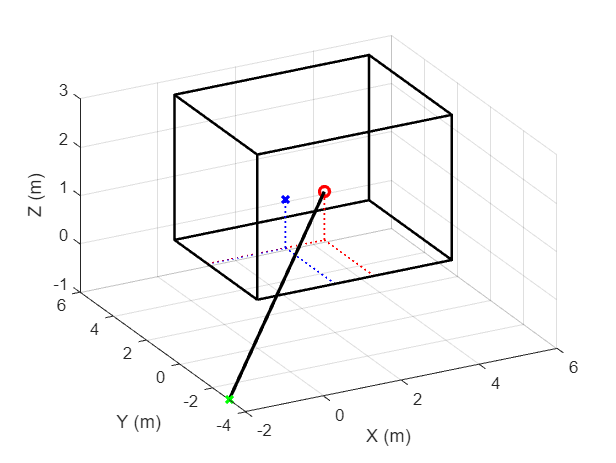

plot3(imageSource(1),imageSource(2),imageSource(3),"gx",LineWidth=2)
plot3([imageSource(1) receiver_coords(1)], ...
      [imageSource(2) receiver_coords(2)], ...
      [imageSource(3) receiver_coords(3)],Color="k",LineWidth=2)

### Visualize Multiple Images

To calculate the room impulse response, add the contributions of a large number of source images. 

Extend the visible space around the room to ensure the images appear in the plot.

fig2 = figure;

plotRoom(room_dimensions,receiver_coords,source_coords,fig2)

Lx = room_dimensions(1); 
Ly = room_dimensions(2);
Lz = room_dimensions(3);

xlim([-3*Lx,3*Lx]);
ylim([-3*Ly,3*Ly]);
zlim([-3*Lz,3*Lz]);

Visualize a subset of the source images. Compute the image coordinates based on equations 6 and 7 in [2].

Model the eight combinations stemming from possible reflections along the *x-*, *y-* and *z-* axes.

audioArray = source_coords(1);
y = source_coords(2);
z = source_coords(3);
sourceXYZ = [-audioArray -y -z;...
             -audioArray -y  z;...
             -audioArray  y -z;...
             -audioArray  y  z;...
              audioArray -y -z;...
              audioArray -y  z;...
              audioArray  y -z;...
              audioArray  y  z].';

Model scenarios with multiple reflections by looping over the *x-*, *y-* and *z-* axes. These loops have infinite ranges in theory. For now, select arbitrary limits for the loops. 

Note: use Step in RUN section under LIVE EDITOR menu to visualize the drawing process of each image by traversing the for loop.

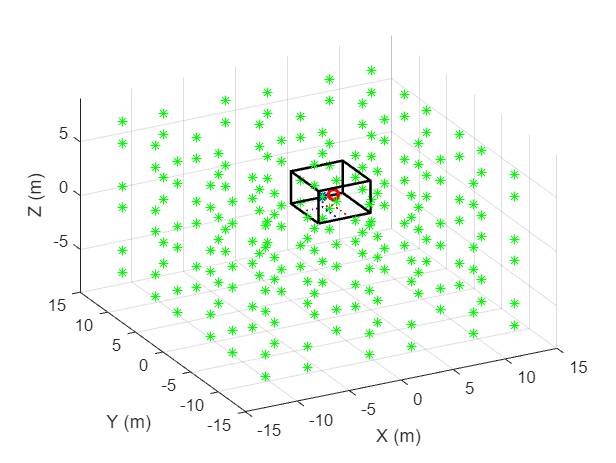

% Increase the range to plot more images
nVect = -2:2;
lVect = -2:2;
mVect = -2:2;

for n = nVect
    for l = lVect
        for m = mVect
            xyz = [n*2*Lx; l*2*Ly; m*2*Lz];
            isourceCoords = xyz - sourceXYZ;
            for kk=1:8
                isourceCoord=isourceCoords(:,kk);
                plot3(isourceCoord(1),isourceCoord(2),isourceCoord(3),"g*")
            end 
        end
    end
end

### Restricting the Number of Simulated Images

The number of images is theoretically infinite. Restrict the number of images by limiting the computed impulse response length to the time by which the reverberated sound pressure drops below a certain level. Here, you use the reverberation time RT60 [3], which is the time by which the sound level has dropped by 60 dB.

Use Sabine's formula to calculate RT60. 

#### Define Wall Absorption Coefficientsr

First, define the absorption coefficients of the walls. The absorption coefficient is a measure of how much sound is absorbed (rather than reflected) when hitting a surface. 

The absorption coefficients are frequency-dependent, and are defined at the frequencies defined in the variable `FVect`. The absorption coeffiecients of common wall materials can be found at [https://www.acoustic-supplies.com/absorption-co.](https://www.acoustic-supplies.com/absorption-co.) See [WallMaterialAbsorptionCoefficients.m](matlab:open('./WallMaterialAbsorptionCoefficients.m')) for documentation.

absorp_floor = WallMaterialAbsorptionCoefficients(material_floor);
absorp_front = WallMaterialAbsorptionCoefficients(material_front);
absorp_left = WallMaterialAbsorptionCoefficients(material_left);
absorp_back = WallMaterialAbsorptionCoefficients(material_back);
absorp_right = WallMaterialAbsorptionCoefficients(material_right);
absorp_ceil = WallMaterialAbsorptionCoefficients(material_ceil);

FVect = absorp_floor.freqs;

A = [absorp_floor.abs_coeffs;...
    absorp_front.abs_coeffs;...
    absorp_left.abs_coeffs;...
    absorp_back.abs_coeffs;...
    absorp_right.abs_coeffs;...
    absorp_ceil.abs_coeffs].';

#### Estimate RT60

Compute RT60 based on Sabine's formula.

First, compute the room's volume.

V = Lx*Ly*Lz;

Next, compute the total wall surface area of the room.

WallXZ = Lx*Lz;
WallYZ = Ly*Lz;
WallXY = Lx*Ly;

Compute the frequency-dependent effective absorbing area of the room surfaces.

S = WallYZ*(A(:,1)+A(:,2))+WallXZ.*(A(:,3)+A(:,4))+WallXY.*(A(:,5)+A(:,6));

Compute the frequency-dependent RT60, in seconds, based on Sabine's equation. Notice that RT60 is frequency-dependent: There are 6 different RT60 values, one for each frequency band.

c  = 343; % Speed of sound (m/s)
RT60 = (55.25/c)*V./S;

Deduce the maximum impulse response length (in samples) based on the largest value in RT60. 

impResLength = fix(max(RT60)*fs);

Express the maximum range of the impulse response in meters.

impResRange=c*(1/fs)*impResLength;

Use this value to limit the range over which to compute images. In this example, to limit the run time, you restrict the loop ranges to [-10;10].

nMax = min(ceil(impResRange./(2.*Lx)),10);
lMax = min(ceil(impResRange./(2.*Ly)),10);
mMax = min(ceil(impResRange./(2.*Lz)),10);

### Derive Contribution of One Image

In this section, you derive the contribution of one image to the room impulse response. 

You later obtain the full room impulse response by summing the contributions of all images under consideration.

Derive the pressure reflection coefficients from the absorption coefficients.

B=sqrt(1-A);

Store the reflection coefficients for each wall in a separate variable.

BX1=B(:,1);
BX2=B(:,2); 
BY1=B(:,3); 
BY2=B(:,4); 
BZ1=B(:,5); 
BZ2=B(:,6);

Model the eight permutations representing the absence or presence of reflection on the *x-*, *y-*, and *z-* axes.

surface_coeff=[0 0 0; 0 0 1; 0 1 0; 0 1 1; 1 0 0; 1 0 1; 1 1 0; 1 1 1];
q = surface_coeff(:,1).'; 
j = surface_coeff(:,2).';
k = surface_coeff(:,3).'; 

In this section, you focus on the contribution of a single image. Select index values corresponding to an arbitrary image. 

n = 1;
l = 1;
m = 1;
p = 1;

#### Compute Image Delay

The contribution of each image is defined by two values:

- Delay: The time it takes the signal to reach the receiver. 

- Power: The (frequency-dependent) energy level of the signal when it reaches the receiver.

You start by computing the image delay. The delay is related to the total distance traveled by the wave from the image to the receiver.

Get the coordinates of the image.

isourceCoord = [n*2*Lx; l*2*Ly; m*2*Lz] - sourceXYZ(:,p);

Calculate the delay (in samples) at which the contribution occurs.

dist = norm((isourceCoord(:)-receiver_coords(:)),2);
delay = (fs/c).*dist;

#### Compute Image Power

Now compute the frequency-dependent magnitude of the contribution.

ImagePower = BX1.^abs(n-q(p)).*BY1.^abs(l-j(p)).*BZ1.^abs(m-k(p)).*BX2.^abs(n).*(BY2.^abs(l)).*(BZ2.^abs(m));

#### Derive Image Contribution

The image power is only defined at 6 frequencies. Here, you first interpolate the response to the entire frequency (Nyquist) range, and then perform an inverse FFT operation to derive the image's contribution to the impulse response. 

Extend the energy level to incorporate zero and Nyquist frequencies.

FVect2=[0 FVect fs/2]';
ImagePower2 = [ImagePower(1); ImagePower(:); ImagePower(6)];

In this example, use an FFT length of 512.

FFTLength = 512; 
HalfLength = fix(FFTLength./2);
OneSidedLength = HalfLength+1;

Interpolate the response to the entire frequency range.

ImagePower2 = interp1(FVect2./(fs/2),ImagePower2,linspace(0,1,257)).';

Convert the response to two-sided.

ImagePower2 = [ImagePower2; conj(ImagePower2(HalfLength:-1:2))];

Convert the frequency response to the time-based contribution of the image.

h_ImagePower = real(ifft(ImagePower2,FFTLength));

Smooth the response by applying a Hann window.

win = hann(FFTLength+1);
h_ImagePower = win.*[h_ImagePower(OneSidedLength:FFTLength); ...
                     h_ImagePower(1:OneSidedLength)];

## HRTF Modeling

In this section, you derive the image's contribution at the ears of a listener located at the receiver coordinates by using 3-D head-related transfer function (HRTF) interpolation.

Load the HRTF data set.

HRTF_Dataset = load(HRTF_dataset_file);

Express the `hrtfData `as an array of size (Number of source measurements) × 2 × (Sample lengths). 

if strcmp(HRTF_dataset_file, 'ReferenceHRTF.mat') % use default ARI dataset
    hrtfData = permute(double(HRTF_Dataset.hrtfData),[2,3,1]);
    sourcePosition = HRTF_Dataset.sourcePosition(:,[1,2]);
else % use custom dataset
    hrtfData = permute(double(HRTF_Dataset.hM),[2 3 1]);
    sourcePosition = HRTF_Dataset.meta.pos(:,[1 2]);
end
sourcePosition(:,1) = sourcePosition(:,1) - 180;

  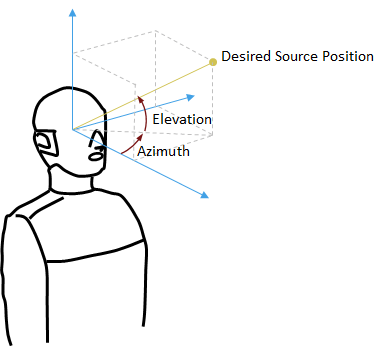

Calculate the elevation and azimuth corresponding to the coordinates of the image source.

sensor_xyz=receiver_coords;
xyz=isourceCoord-sensor_xyz;
hyp = sqrt(xyz(1)^2+xyz(2)^2); 
elevation = atan(xyz(3)./(hyp+eps)); 
azimuth = atan2(xyz(2),xyz(1));

The desired HRTF position before head tracking is formed by the computed elevation and azimuth.

desiredPosition_pre_head_tracking = [azimuth elevation]*180/pi;

### Compute Overall Room Impulse Response with HRTF

#### by summing the contributions of individual images

See [HelperImageSource.m](matlab:open('./HelperImageSource.m')) for full implementation.

if ~isLoadFile
    h = HelperImageSource(room_dimensions, receiver_coords, source_coords, A, FVect, fs, true, hrtfData, sourcePosition);
end

Write the estimated room impulse response to file.

if ~isLoadFile
    myDataManager.h_table = table(h);
    myDataManager.writeToFile(".\data\"+"h_"+timeToString()+".txt")
end

h = permute(h, [2 1]);

## Signal Processing

This section shows how the original audio signal is processed to achieve binaural reproduction of simulating the sound source played inside the virtual room with head tracking.

#### Load Audio

[audioArray,originalSampleRate] = audioread(audio_file);

Keep only one channel.

audioArray = mono(audioArray); 

Resample to 48kHz.

audioArray = resample(audioArray,fs,originalSampleRate);

Create a SignalSource object.

sigsrc = dsp.SignalSource(audioArray, ...
    'SamplesPerFrame',fs/10, ...
    'SignalEndAction','Cyclic repetition');

#### Create audioDeviceWriter Object

deviceWriter = audioDeviceWriter('SampleRate',fs);
%% Create FIR Filters 

#### Create FIR filters for Binaural HRTF Filtering

FIR = cell(1,4);
FIR{1} = dsp.FIRFilter('NumeratorSource','Input port');
FIR{2} = dsp.FIRFilter('NumeratorSource','Input port');
FIR{3} = dsp.FIRFilter('NumeratorSource','Input port');
FIR{4} = dsp.FIRFilter('NumeratorSource','Input port');

#### Initialize Orientation Viewer

viewer = HelperOrientationViewer('Title',{'IMU Filter'});

### Audio Processing Loop

Count IMU overruns and audio underruns.

if isUseArduino
    imuOverruns = 0;
    last_imuOverrun = 0;
end
audioUnderruns = 0;
last_audioUnderruns = 0;

Initialize HRTF filter array and filtered audio array.

audioFiltered = zeros(sigsrc.SamplesPerFrame,2);

The figure below shows the orientation axsis for accelerometer and gyroscope of the MPU-9250 IMU sensor.

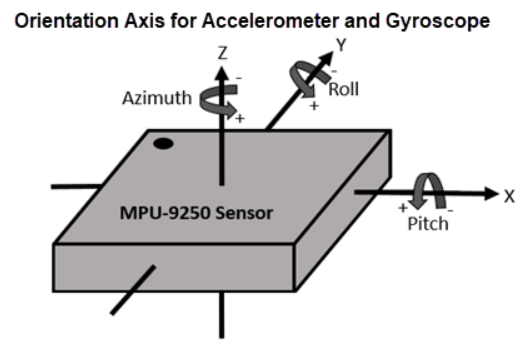

As shown in the figure above, yaw (azimuth) corresponds to horizontal rotation; pitch corresponds to vertical rotation. The filter "imufilter" is required to fuse the data collected from the accelerometer and gyroscope of the IMU sensor.

The audio processing loop below uses imufilter to estimate orientation and update the viewer as the sensor moves for time specified by stop_timer. The desired position can be obtained by adding 1. the computed azimuth and elevation between the source and receiver and 2. yaw and pitch fused from the sensor. The audio will first convolve with the room impulse response estimated using the image-source method, then filtered by the HRTF impulse response at the desired position.

if isUseArduino
    stop_timer = 100;
    
    tic; 
    
    while(toc < stop_timer)
        [data,overrun] = read(imu);
        % print overrun
        if overrun > 0
            last_imuOverrun = imuOverruns;
            imuOverruns = imuOverruns + overrun;
            if last_imuOverrun ~= imuOverruns
                fprintf('IMU Overruns = %i\n', imuOverruns);
            end
        end
    
        % get acceleration and gyroscope
        accel = data.Acceleration;
        gyro = data.AngularVelocity;
    
        % Fuse IMU sensor data to estimate the orientation of the sensor.
        rotators = FUSE(accel,gyro); 
        for j = numel(rotators) 
            viewer(rotators(j)); 
        end
        % Convert the orientation from a quaternion representation to pitch and yaw in Euler angles.
        ypr = eulerd(rotators,'zyx','frame');
        yaw = ypr(end,1);
        pitch = ypr(end,2);
    
        % Add yaw and pitch to the position data obtained from location
        desiredPosition = desiredPosition_pre_head_tracking + [yaw, pitch];
        
        % Obtain a pair of HRTFs at the desired position.
        interpolatedIR = double(squeeze(interpolateHRTF(hrtfData,sourcePosition,desiredPosition)));
        
        % Read audio from file
        audioArray = sigsrc();
        
        % Apply HRTFs
        audioFiltered(:,1) = FIR{1}(audioArray, h(1,:)); % Left
        audioFiltered(:,1) = FIR{3}(audioFiltered(:,1), interpolatedIR(1,:));
        audioFiltered(:,2) = FIR{2}(audioArray, h(2,:)); % Right
        audioFiltered(:,2) = FIR{4}(audioFiltered(:,2), interpolatedIR(2,:));
        
        % count audio underruns
        last_audioUnderruns = audioUnderruns;
        % play audio
        audioUnderruns = audioUnderruns + deviceWriter(audioFiltered); 
        if last_audioUnderruns ~= audioUnderruns
            fprintf('Audio Underruns = %i\n', audioUnderruns);
        end
    end
end

#### Simulation of head movements without using Arduino.

Simulation of horizontal rotation (yaw = -180 --> 180).

if ~isUseArduino
    stop_timer = 15;
    tic; 
    yaw = -180;
    pitch = 0;
    fprintf("Now simulating horizontal rotation (yaw).\n")
    while(toc < stop_timer)
        yaw = yaw + 5;
        if yaw >= 180
            yaw = yaw-360;
        end
    
        % Add yaw and pitch to the position data obtained from location
        desiredPosition = desiredPosition_pre_head_tracking + [yaw, pitch];
        
        % Obtain a pair of HRTFs at the desired position.
        interpolatedIR = double(squeeze(interpolateHRTF(hrtfData,sourcePosition,desiredPosition)));
        
        % Read audio from file
        audioArray = sigsrc();
        
        % Apply HRTFs
        audioFiltered(:,1) = FIR{1}(audioArray, h(1,:)); % Left
        audioFiltered(:,1) = FIR{3}(audioFiltered(:,1), interpolatedIR(1,:));
        audioFiltered(:,2) = FIR{2}(audioArray, h(2,:)); % Right
        audioFiltered(:,2) = FIR{4}(audioFiltered(:,2), interpolatedIR(2,:));
        
        % count audio underruns
        last_audioUnderruns = audioUnderruns;
        % play audio
        audioUnderruns = audioUnderruns + deviceWriter(audioFiltered); 
        if last_audioUnderruns ~= audioUnderruns
            fprintf('Audio Underruns = %i\n', audioUnderruns);
        end
    end
end

Now simulating horizontal rotation (yaw).


pause(2);

Simulation of vertical nodding (pitch = -30 <-->80).

if ~isUseArduino
    stop_timer = 15;
    tic; 
    yaw = 0;
    pitch = -30;
    adder = 3;
    fprintf("Now simulating vertical nodding (pitch).\n")
    while(toc < stop_timer)
        pitch = pitch + adder;
        if pitch > 80-adder || pitch < -30-adder
            adder = -adder;
        end
    
        % Add yaw and pitch to the position data obtained from location
        desiredPosition = desiredPosition_pre_head_tracking + [yaw, pitch];
        
        % Obtain a pair of HRTFs at the desired position.
        interpolatedIR = double(squeeze(interpolateHRTF(hrtfData,sourcePosition,desiredPosition)));
        
        % Read audio from file
        audioArray = sigsrc();
        
        % Apply HRTFs
        audioFiltered(:,1) = FIR{1}(audioArray, h(1,:)); % Left
        audioFiltered(:,1) = FIR{3}(audioFiltered(:,1), interpolatedIR(1,:));
        audioFiltered(:,2) = FIR{2}(audioArray, h(2,:)); % Right
        audioFiltered(:,2) = FIR{4}(audioFiltered(:,2), interpolatedIR(2,:));
        
        % count audio underruns
        last_audioUnderruns = audioUnderruns;
        % play audio
        audioUnderruns = audioUnderruns + deviceWriter(audioFiltered); 
        if last_audioUnderruns ~= audioUnderruns
            fprintf('Audio Underruns = %i\n', audioUnderruns);
        end
    end
end

Now simulating vertical nodding (pitch).


Audio Underruns = 12000


## Cleanup

release(sigsrc)
release(deviceWriter)
clear imu a

## Helper Functions

function s = timeToString()
    % Get the current date and time
    currentDateTime = datetime('now');
    
    % Format the date and time as a string in the desired format
    s = string(currentDateTime.Year) + "-" + ...
        sprintf('%02d', currentDateTime.Month) + "-" + ...
        sprintf('%02d', currentDateTime.Day) + "-" + ...
        sprintf('%02d', currentDateTime.Hour) + "-" + ...
        sprintf('%02d', currentDateTime.Minute) + "-" + ...
        sprintf('%02d', floor(currentDateTime.Second));
end